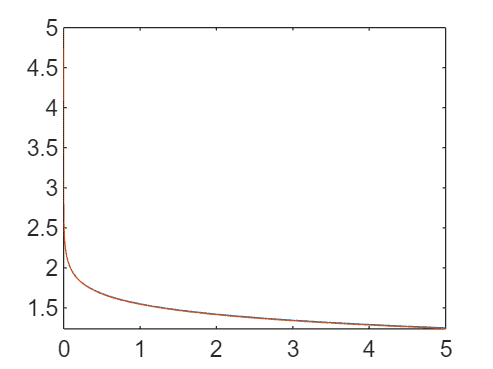

x=[0.4 0.8 1.2 1.6 2 2.3];
y=[800 975 1500 1950 2900 3000];
syms A B
f1=A.*sum(10.^(2*B.*x))-sum(y.*10.^(B.*x));
f2=A.*sum(x.*10.^(2*B.*x))-sum(x.*y.*10.^(B.*x));
fimplicit(f1)
hold on
fimplicit(f2)
hold off

vpasolve([f1 f2]',[A B],"Random",true)

ans = struct with fields:
    A: 0
    B: 48.189249433035063927816075383444




fsolve([f1 f2], [0.3 540])

'fsolve' requires Optimization Toolbox.